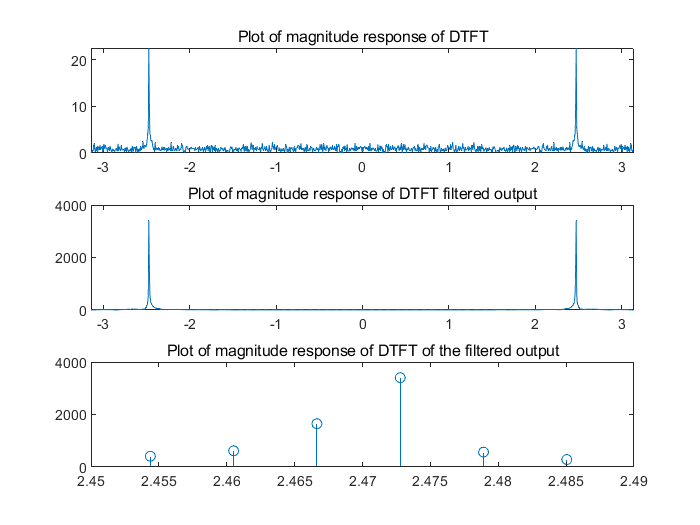

load pcm;
sig1 = pcm(100:200);
sig2 = pcm(100:1100);
n = 0:length(sig1)-1;
[X,w] = DTFT(sig2,0);
f = IIRfilter(pcm);
f1 = f(100:200);
f2 = f(100:1100);
theta=(3146/8000)*2*pi;
[F,w] = DTFT(f2,0);
w1 = w(w>(theta-0.02));
w1 = w1(w1<(theta+0.02));
X1 = X(w>(theta-0.02) & w<(theta+0.02));
f_X1 = F(w>(theta-0.02) & w<(theta+0.02));

% subplot(311),plot(n,sig1);title('Plot of 101 samples response of the orignal signal');
% subplot(312),plot(n,f1);title('Plot of 101 samples response of the filtered output');
% subplot(313),stem(w1,abs(X1));title('Plot of magnitude response of DTFT of the orignal signal');


subplot(311),plot(w,abs(X));title('Plot of magnitude response of DTFT');xlim([-pi pi]);
subplot(312),plot(w,abs(F));title('Plot of magnitude response of DTFT filtered output');xlim([-pi pi]);
subplot(313),stem(w1,abs(f_X1));title('Plot of magnitude response of DTFT of the filtered output');